# Getting Started Guide

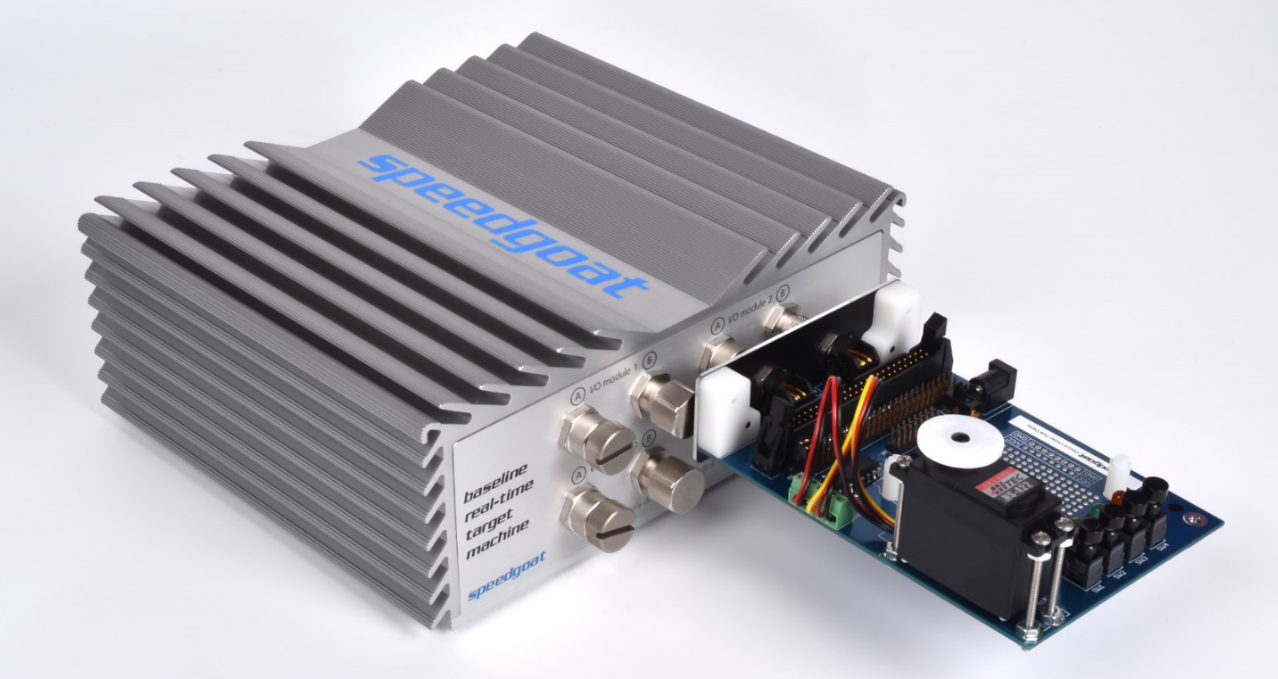

## **Description**

The Getting Started Demo by Speedgoat, takes you through the typical real-time simulation and testing workflows using simple exercises that include Simulink models and Speedgoat real-time target machines with I/O connected to a Device Under Test (DUT) with an electric DC motor, switches, and LEDs. 

The demo leverages the Speedgoat [Getting Started Demo Kit](https://www.speedgoat.com/products-services/demo-kits/getting-started-demo), which features an electric servo DC motor, a H-bridge and a potentiometer feedback.

This kit seamless operates with the cost-effective [IO397 FGPA I/O Module](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io397) and is delivered with a custom FPGA implementation file integrating [PWM generation](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-code-module-pwm-generation),  [I2C communication](https://www.speedgoat.com/products-services/communications-protocols/i2c), and General Purpose Digital I/O code modules.

This demo kit is also covered by the [Simulink Real-Time training ](https://www.speedgoat.com/products-services/services/training-and-consulting)offered by MathWorks.

## System Requirements

   ** MathWorks products**

- [MATLAB®](https://www.mathworks.com/products/matlab.html)

- [Simulink®](https://www.mathworks.com/products/simulink.html)

- [Simulink Real-Time™](https://www.mathworks.com/products/simulink-real-time.html?s_tid=srchtitle)  -  [product requirements](https://www.mathworks.com/support/requirements/simulink-real-time.html)

    **Speedgoat products**

- [Getting Started Demo Kit](https://www.speedgoat.com/products-services/demo-kits/getting-started-demo)

- [Speedgoat real-time target machine](https://www.speedgoat.com/products-services/real-time-target-machines) equipped with a [IO397 FPGA I/O Module](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io397)

## Connect and Set Up Demo Kit

Prepare the demo hardware with the following three steps:

1.Connect hardware kit to the IO397 I/O module either by:

- Using the M12 cables provided or

- Directly plugging the DUT Demo hardware into the M12 connectors of the real-time target machine (see image below).

    

2. Power the Demo: While the DUT demo requires a 5 Vdc power supply, the Baseline real-time target machine includes a 5 Vdc power supply. Set the power switch SW5 upwards to use the Baseline power supply.  No external power supply should be connected.

Alternative power options (not recommended): By setting the power switch SW5 downwards, it is possible to use an external power supply from J2. To use an external power supply connect a regulated 5 Vdc power supply using a 5.5mm/2.1mm 5 Vdc Barrel Jack connector (not included with DUT demo).

## 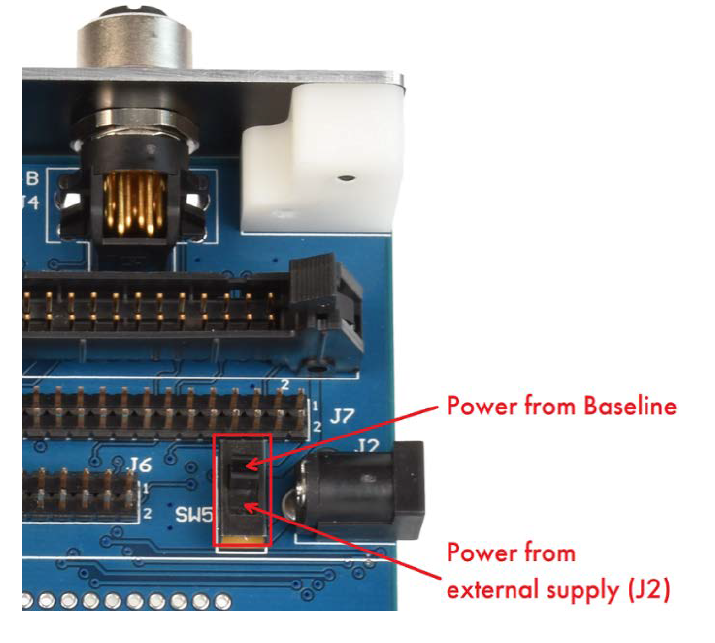

## Exercises

## **    Digital I/O Loopback Test**

To test GPIOs, the model sgm_iox_io397_digital_loopback.slx can be used. The model configures GPIOs 1 to 4 as inputs and GPIOs 5 to 8 as outputs.

1. Open Simulink model 

open('sgm_iox_io397_digital_loopback.slx')

2. Execute Real-Time Application with Simulink External Mode

Control of the real-time application with Simulink is limited to connecting a Simulink model to a real-time application through external mode, and then starting the real-time application. Using Simulink external mode is one method to tune parameters. By default, the model connects to the default target computer, as specified in Simulink Real-Time Explorer.

- Select **Simulation** > **Mode** > **External**. A check mark appears next to the menu item **External**. Simulink external mode is activated. Simulink external mode connects the Simulink model to the real-time application as a simple user interface.

- In Simulink Editor, on the toolbar, click the **Build Model** button on the toolbar.

- On the toolbar, click the **Connect To Target** button. The current Simulink model parameters are downloaded from the development computer to the real-time application.

- On the toolbar, click the **Run** button.

            

3. Push the hardware kit pushdown buttons one by one

When a pushdown button is pressed down, the led in front of it should start to blink. For all buttons pressed, all lights will blink (at different frequencies). Use [Simulation Data Inspector](https://www.mathworks.com/help/releases/R2020b/slrealtime/ug/inspect-signals-in-external-mode-using-simulation-data-inspector.html) (SDI) and Simulink model dashboard components to visualize LEDs states.

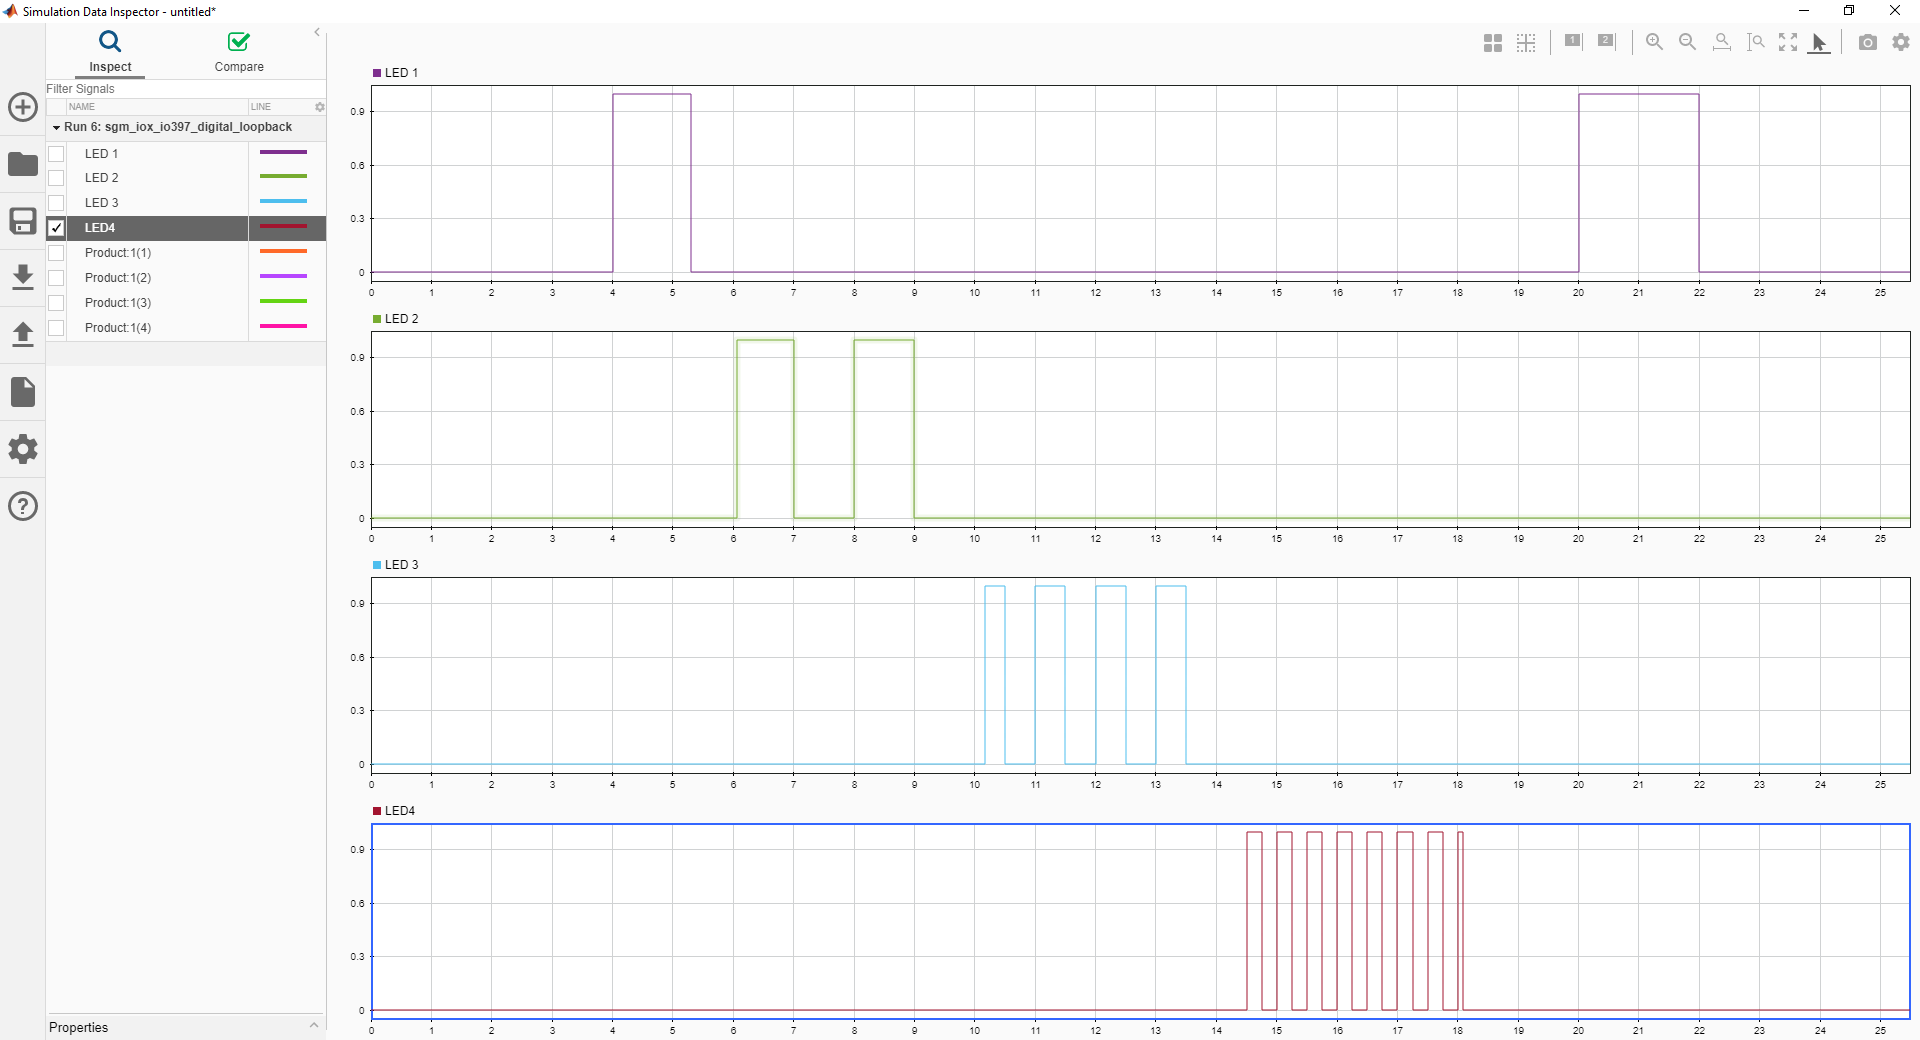

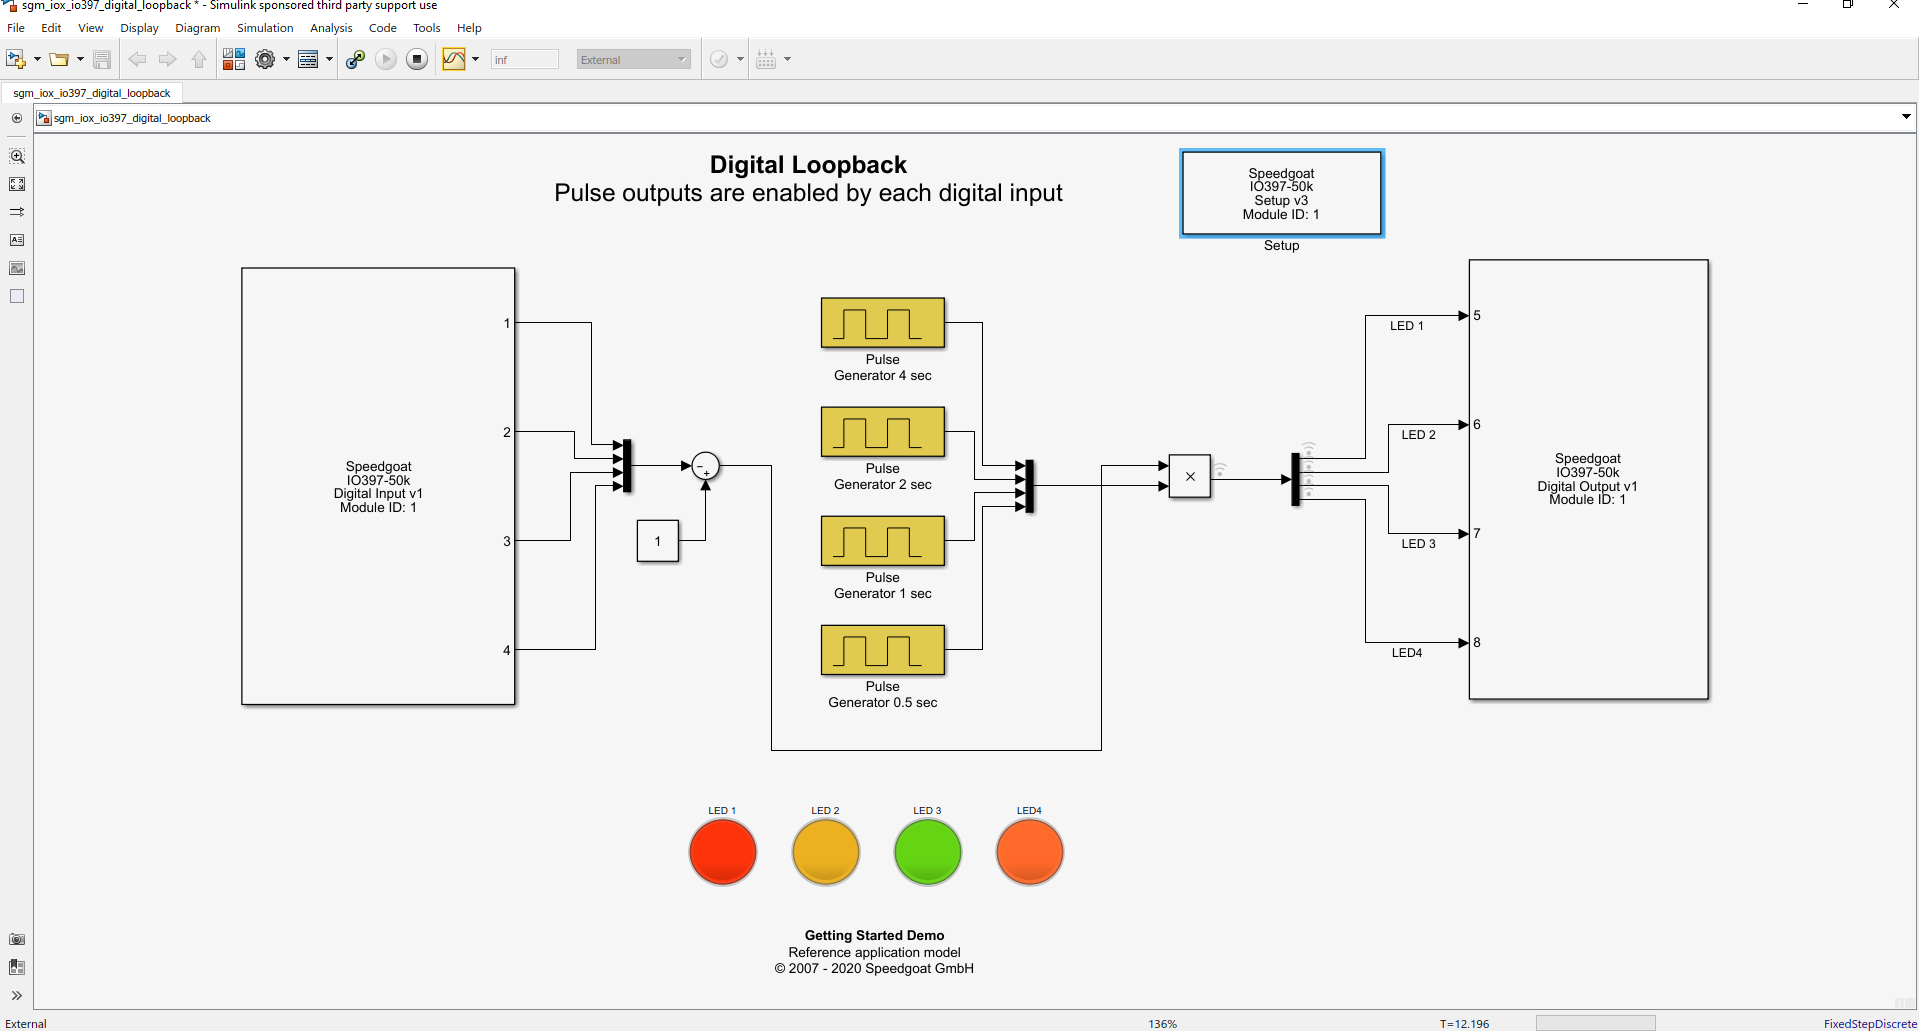

##     Analog I/O Loopback Test

For the analog IOs the model sgm_iox_io397_analog_loopback.slx can be used. The model implements a Filter of the 1st-Order, using the analog output 1 (DAC1) and the analog input 2 (ADC2).

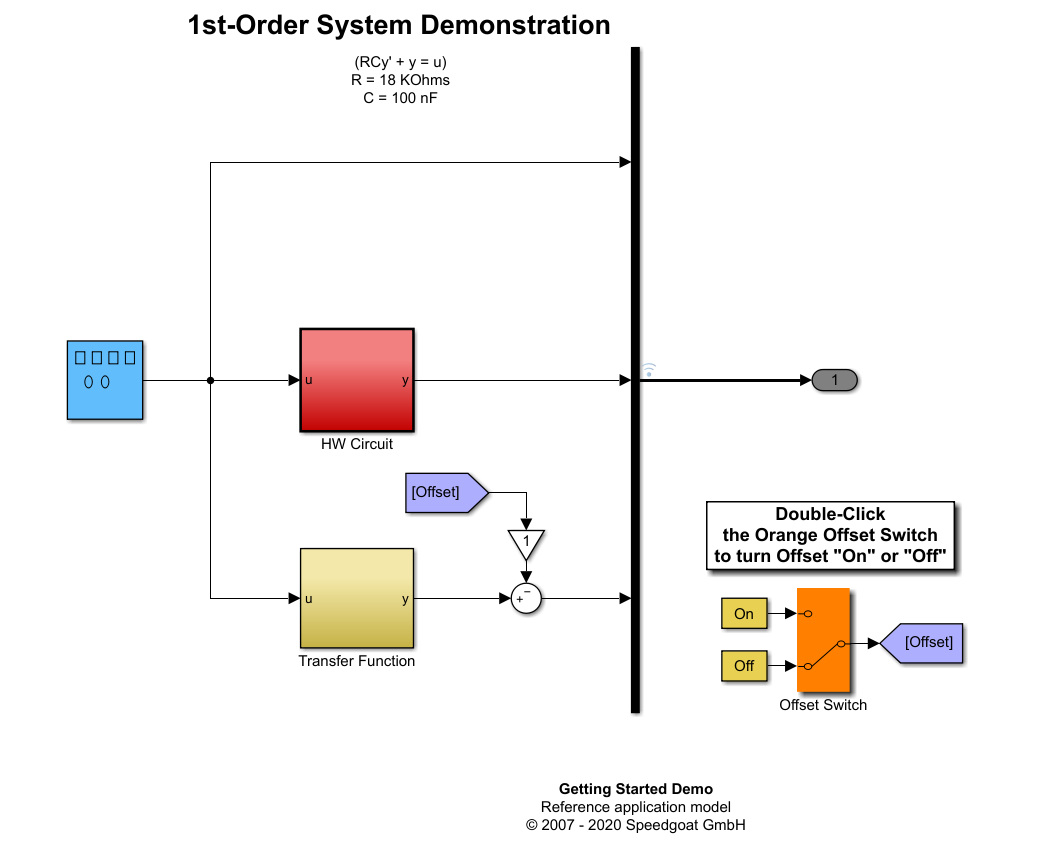

1. Open Simulink model 

 open('sgm_iox_io397_analog_loopback.slx')

2. Execute Real-Time Application with Simulink External Mode

As the model runs, the DAC1 sends a square signal; and ADC2 reads the same signal once it went through the RC filter. The expected loopback analog signal should look as in the [SDI](https://www.mathworks.com/help/releases/R2020b/slrealtime/ug/inspect-signals-in-external-mode-using-simulation-data-inspector.html) scope depicted below (signal in blue).

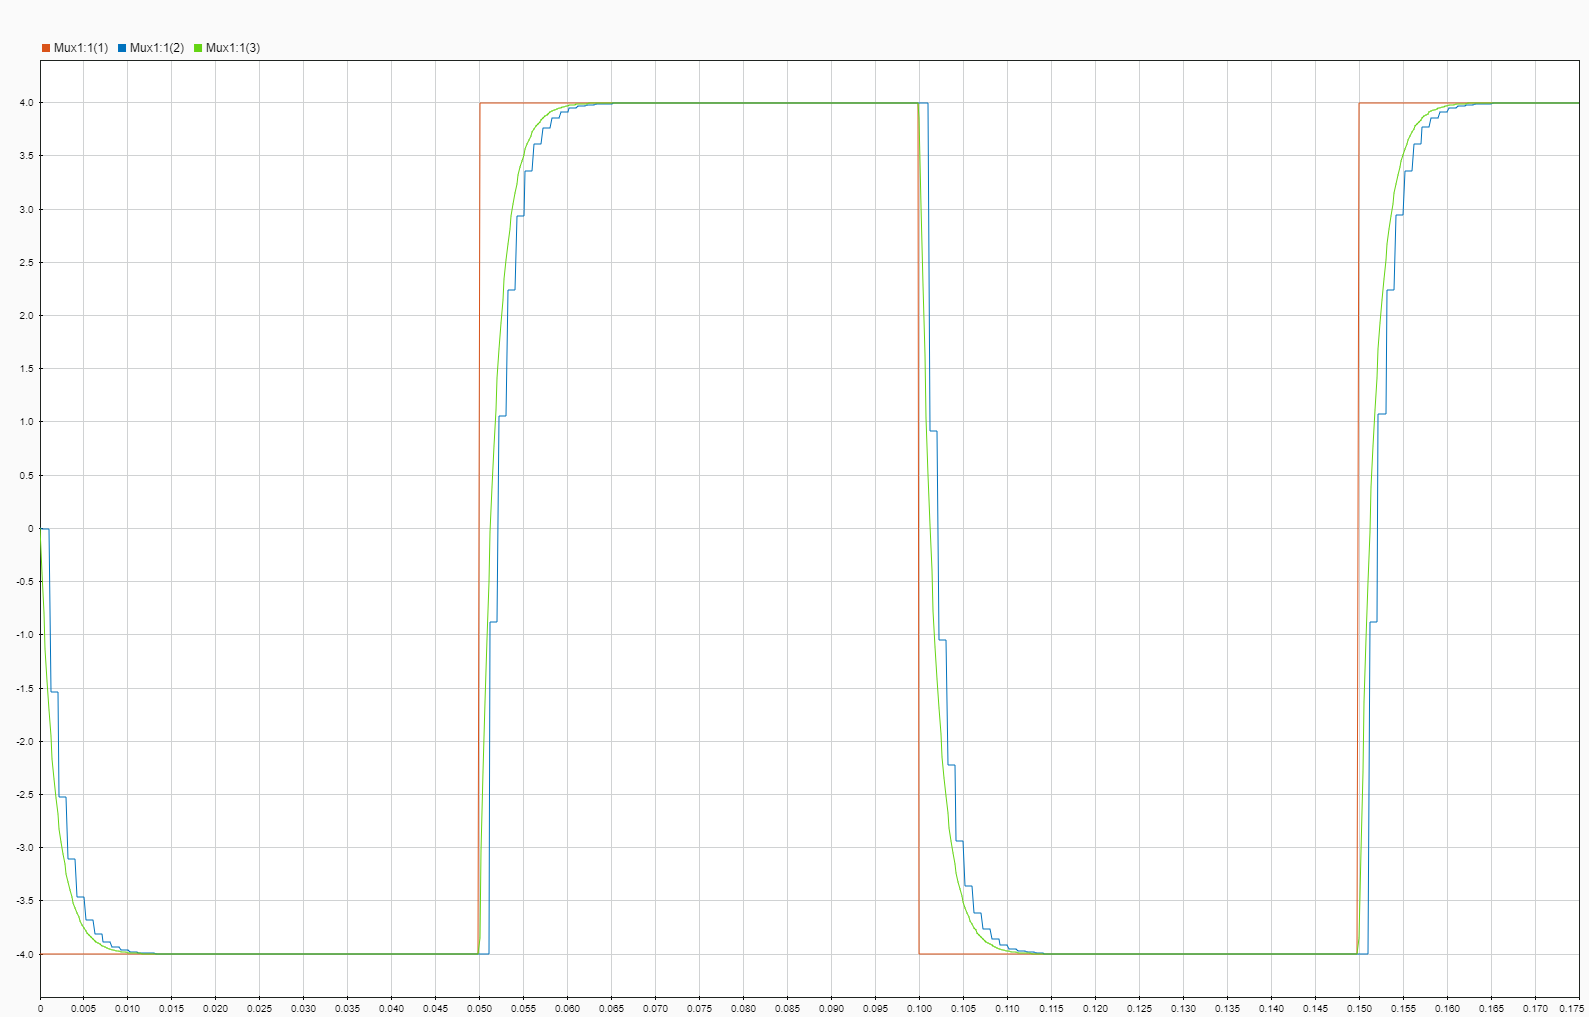

##     I2C Loopback Test

For the I2C IOs the model sgm_com_io397_i2c_loopback.slx can be used. The model configures the I2C master and slave loopback: sent via the I2C slave are read via the I2C master. The I2C slave writes 4 registers in a single channel. 

The registers are:

- Constant: 7

- Sawtooth wave

- Constant: 100

- Constant: 66

Before running I2C test model please check that the hardware kit jumpers are correctly configured for the I2C loopback test:

- linking J7-pin 53 and J7-pin 55

- linking J7-pin 54 and J7-pin 56

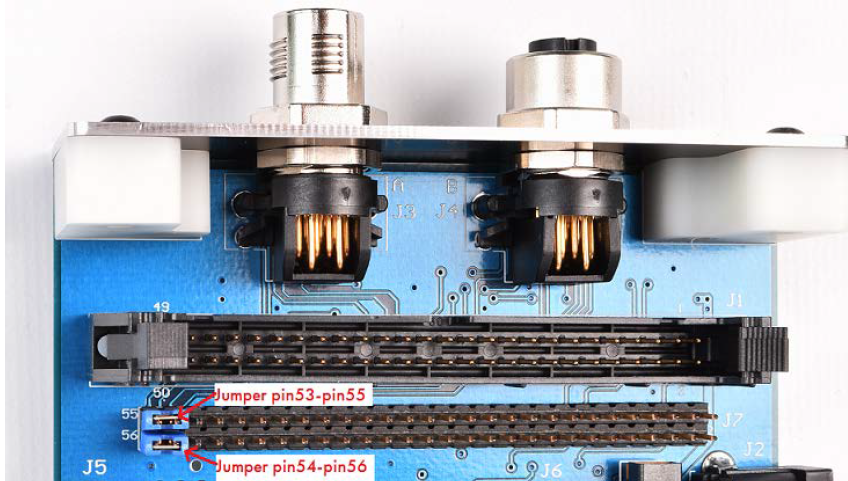

Test the I2C loopback I/O Simulink Real-Time model by:

1. Open Simulink model 

open('sgm_com_io397_i2c_loopback.slx')

2. Execute Real-Time Application with Simulink External Mode

A sample of the SDI visualization can be seen in the figure below.

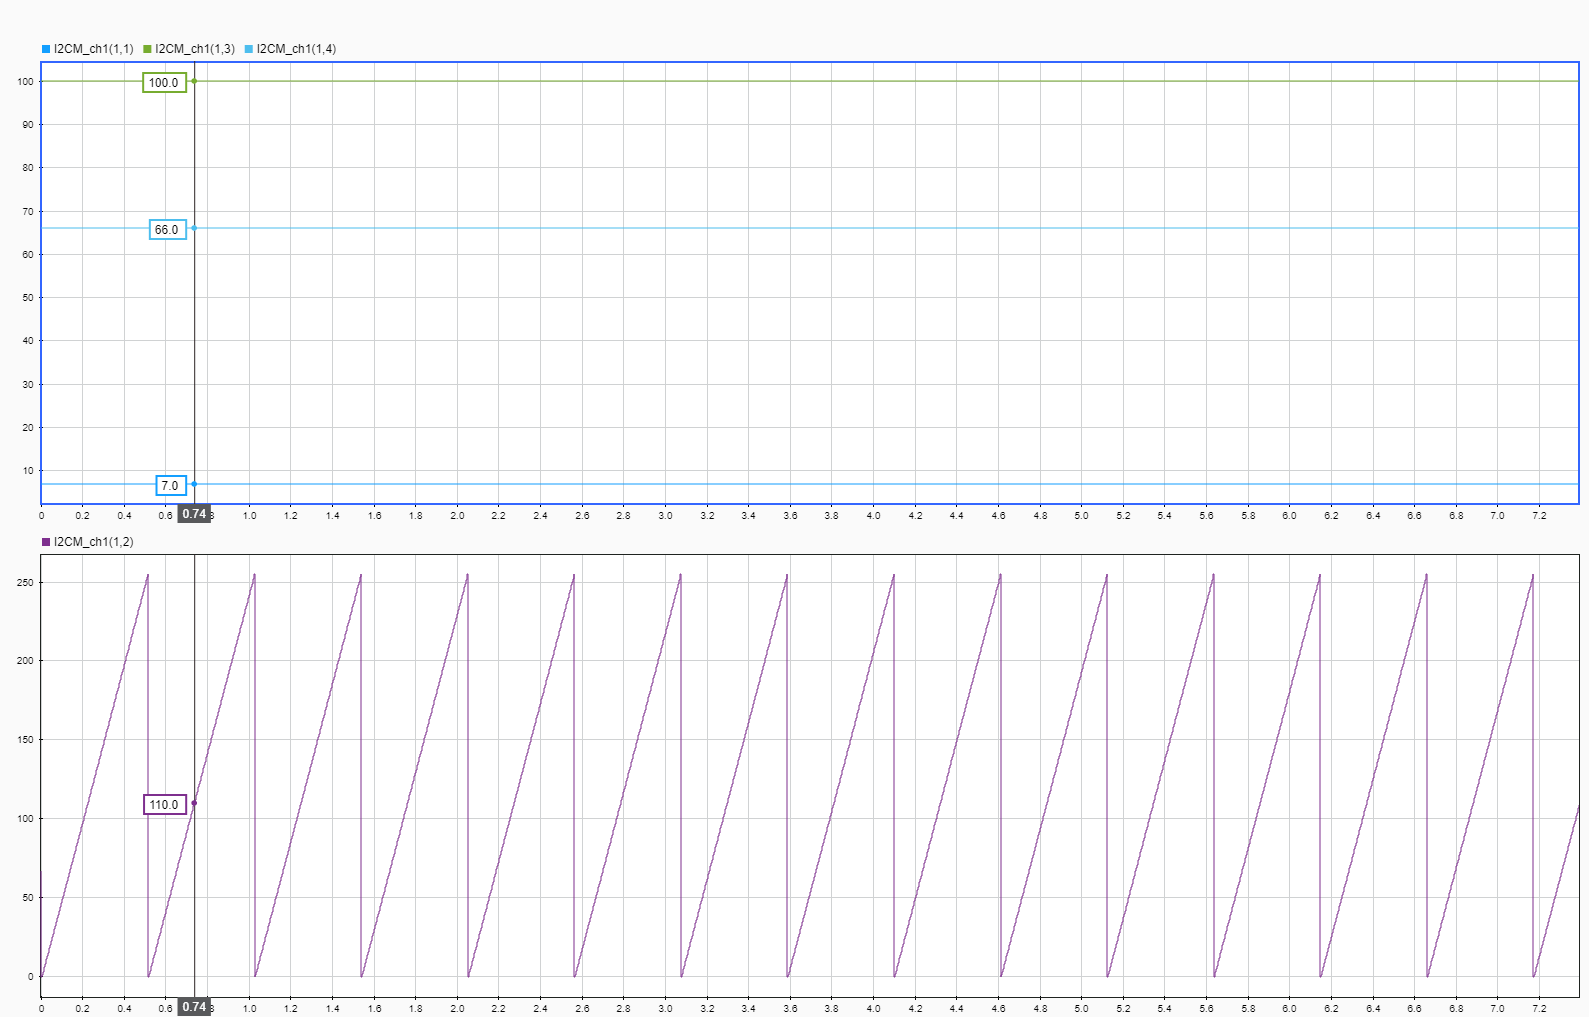

##     Servo Motor Control

For the servo-motor control the model sgm_iox_io397_pwm_motor_control.slx can be used. The model generates a forward and backward PWM signal rotating the servo-motor back and forth. 

Using analog input 1 (ADC1), the position gets read back via the servo potentiometer. The PWM signal is generated using the PWM FPGA Code Module with a 13.33 ns resolution.

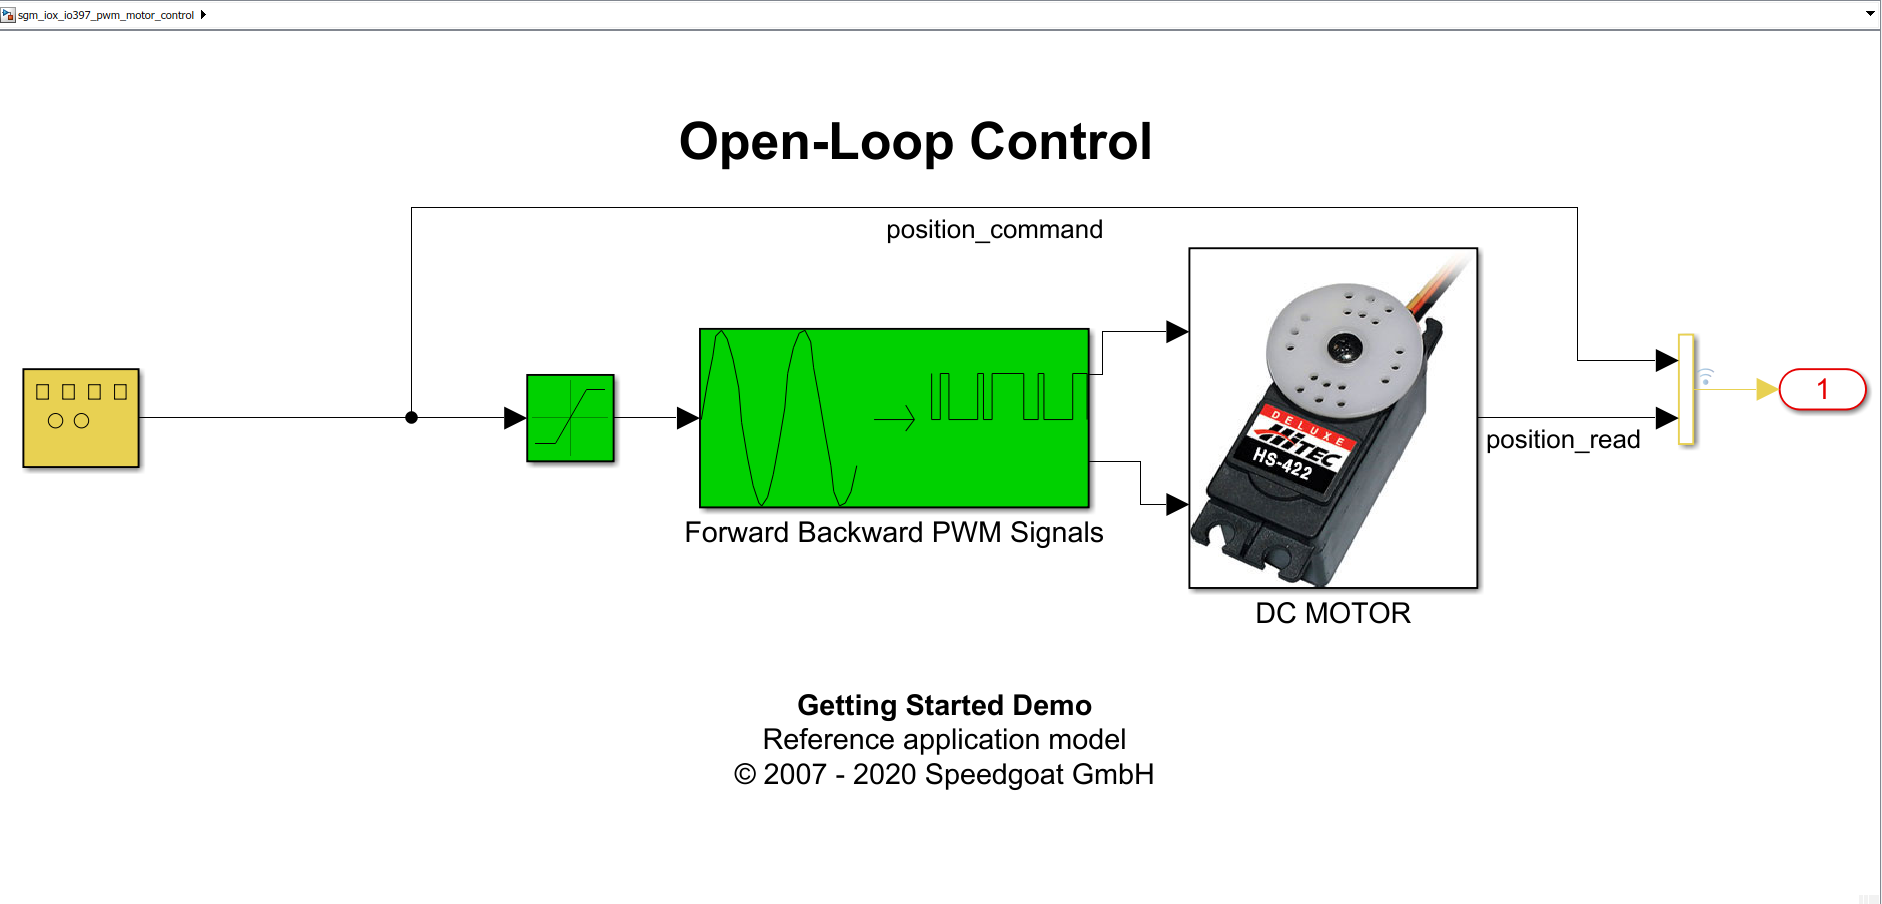

Test the servo motor I/O Simulink Real-Time model by:

1. Open Simulink model 

open('sgm_iox_io397_pwm_motor_control.slx')

2. Execute Real-Time Application with Simulink External Mode

The servo-motor should start rotating back and forth. The position command and the measured servo-motor potentiometer voltage read with SDI are displayed in the figure below.

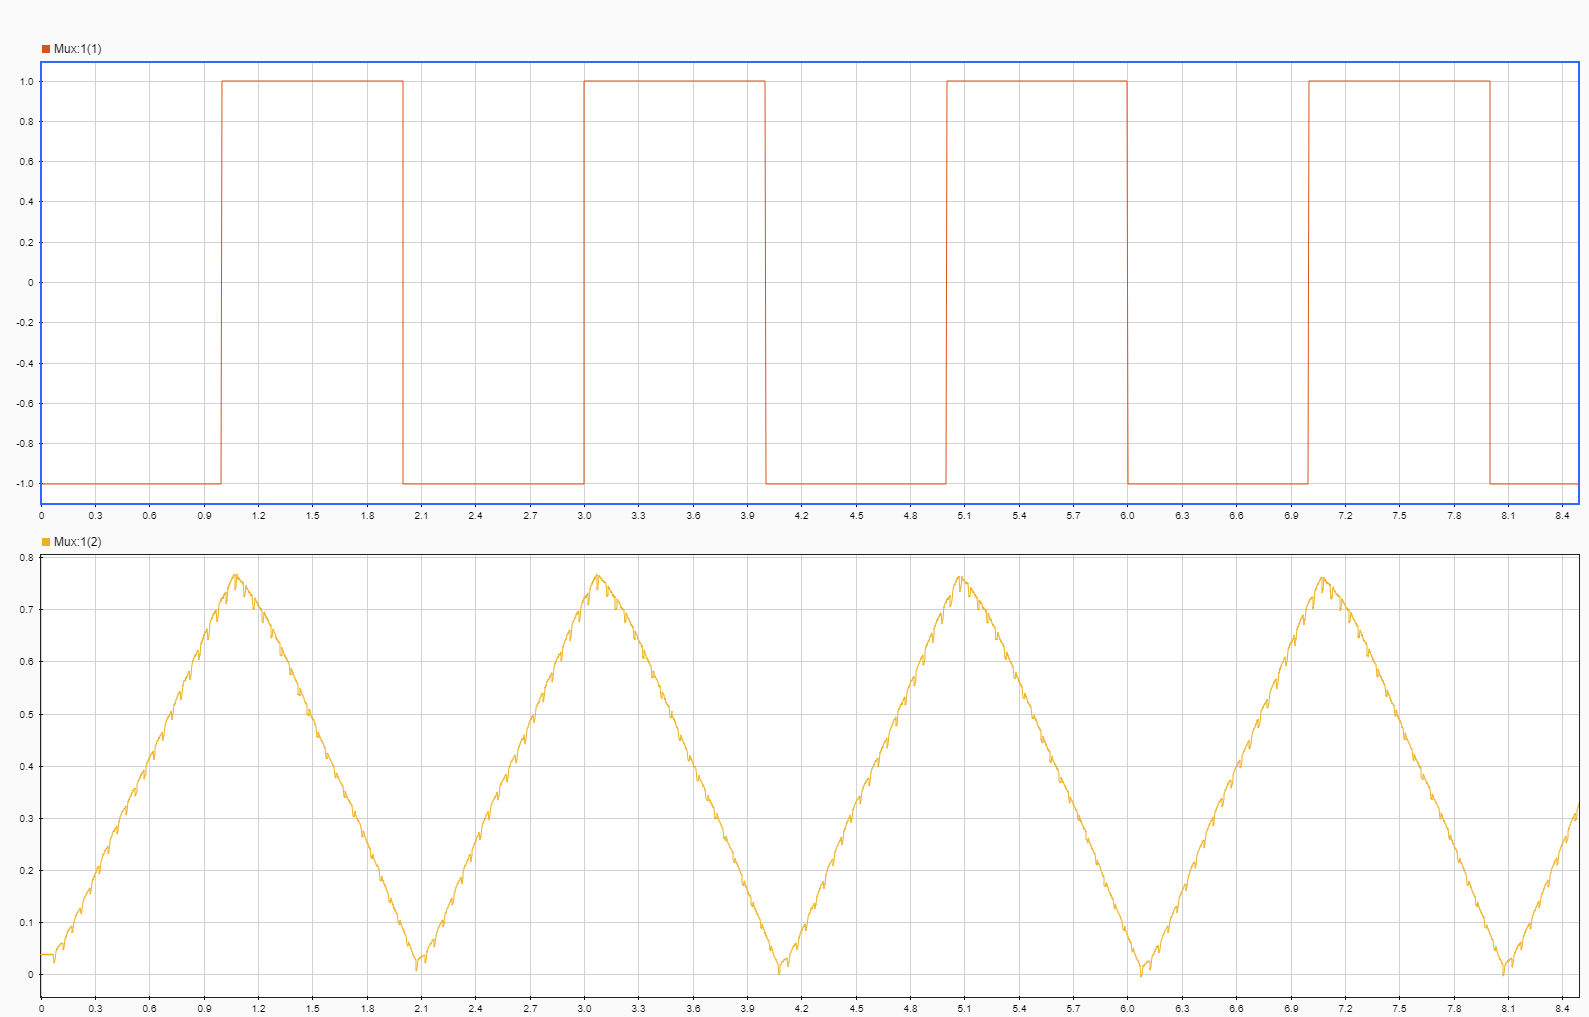

## Related Content

[[Video]: Real-Time Simulation and Testing – Rapid Control Prototyping](https://www.mathworks.com/support/search.html/videos/real-time-simulation-and-testing-rapid-control-prototyping-1600759638781.html?fq=asset_type_name:video%20category:slrealtime/index&page=1)

Detailed introduction to Rapid Control Prototyping using Speedgoat real-time target machines, [Simulink Real-Time™](https://www.mathworks.com/products/simulink-real-time.html?s_tid=srchtitle)  and Speedgoat [Getting Started Demo Ki](https://www.speedgoat.com/products-services/demo-kits/getting-started-demo)t.

[[Video]: Real-Time Simulation and Testing - Hardware-in-the-Loop](https://www.mathworks.com/support/search.html/videos/real-time-simulation-and-testing-with-simulink-real-time-100956.html?fq=asset_type_name:video%20category:ident/index&page=1)

In this webinar a MathWorks’ Engineer demonstrates real-time testing for hardware-in-the-loop simulation and controller design using a DC servo motor.

[[Video:] Using External Mode in Simulink Real-Time](https://www.mathworks.com/videos/using-external-mode-in-simulink-real-time-1599212902496.html?s_tid=srchtitle)

Learn how to use Simulink external mode to establish a communication channel between your Simulink model running on your development computer (host) and the Speedgoat target hardware that runs the real-time application.

[[Video]: User Interfaces for Simulink Real-Time](https://www.mathworks.com/support/search.html/videos/user-interfaces-for-simulink-real-time-1599738400687.html?fq=asset_type_name:video%20category:slrealtime/index&page=1)

Learn how to design apps with App Designer to tune parameters and monitor signals from real-time applications that are running on a Speedgoat target computer. 

[[Video]: Speed Control of a DC Motor Using PWM](https://www.mathworks.com/support/search.html/videos/speed-control-of-a-dc-motor-using-pwm-68962.html?fq=asset_type_name:video%20category:slcontrol/index&page=1)

Design a speed controller for a DC motor using pulse-width modulation (PWM).

[[Example]: DC Servo Motor Parameter Estimation](https://www.mathworks.com/help/sldo/ug/dc-servo-motor-parameter-estimation.html?s_tid=srchtitle)

This example shows how to estimate the parameters of a multi-domain DC servo motor model constructed using various physical modeling products.

Note: this example requires the following additional MathWorks products

- [Simulink Design Optimization](https://www.mathworks.com/products/sl-design-optimization.html)

- [Simscape Driveline](https://www.mathworks.com/products/simscape-driveline.html)

- [Simscape Electrical](https://www.mathworks.com/products/simscape-electrical.html)

[[Success story]: Developing Controls for a Miniature Autonomous Drilling Rig in the Drillbotics Student Competition](https://www.mathworks.com/company/newsletters/articles/developing-controls-for-a-miniature-autonomous-drilling-rig-in-the-drillbotics-student-competition.html?s_tid=srchtitle)

Learn how a team of students from University of Texas at Austin, implemented a real-time control system for nanoRIGv2 leveraging a 2.5HP stepper motor,  using Simulink®, Simulink Real-Time™, and Speedgoat target hardware

## Release Notes

open README.md

## Safety Guidelines

##     Intended Use

The Getting Started Demo Kit  have been designed, developed, and manufactured for evaluation of the real-time products from MathWorks and Speedgoat. This product was not designed, developed, or manufactured for any use involving serious risks or hazards that could lead to death, injury, serious physical damage or loss of any kind without the implementation of exceptionally stringent safety precautions. In particular, such risks and hazards include the use of these devices to monitor nuclear reactions in nuclear power plants, their use in flight control or flight safety systems as well as in the control of mass transportation systems, medical life support systems or weapons systems.

##     Protection Against Electrostatic Discharge

Electrical components that can be damaged by electrostatic discharge (ESD) must be handled accordingly.

##     Packaging

**Electrical Components with Housing**

Does not require special ESD packaging but must be handled properly.

**Electrical Components without housing**

Must be protected by ESD-suitable packaging.

##     Policies and Procedures

Electronic devices are never completely failsafe. If the system fails, the user is responsible for ensuring that other connected devices, e.g. motors, are brought to a secure state.

Safety precautions relevant to industrial control systems (e.g. the provision of safety devices such as emergency stop circuits, etc.) must be observed in accordance with applicable national and international regulations. The same applies for all other devices connected to the system, such as drives.

All tasks such as the installation, commissioning and servicing of devices are only permitted to be carried out by qualified personnel. Qualified personnel are those familiar with the transport, mounting, installation, commissioning and operation of devices who also have the appropriate qualifications (e.g. IEC 60364). National accident prevention regulations must be observed.

Safety notices, connection descriptions (type plate and documentation) and limit values listed in the technical data are to be read carefully before installation and commissioning and must be observed.

##     Transport and Storage

During transport and storage, devices must be protected against undue stress (mechanical loads, temperature, humidity, aggressive atmospheres, etc.).

##     Installation

- Installation must be performed according to the Speedgoat documentation for the real-time target machine. Devices may only be installed by qualified personnel without voltage applied. Before installation, voltage to the control cabinet must be switched off and prevented from being switched on again.

- General safety guidelines and national accident prevention regulations must be observed.

- Electrical installation must be carried out according to applicable guidelines (e.g. line cross sections, fuses, protective ground connections).

##     Operation

**Protection Against Touching Electrical Parts**

To operate, it may be necessary for certain parts to carry dangerous voltage levels over 42 VDC. Touching one of these parts can result in a life-threatening electric shock. This could lead to death, severe injury or damage to equipment. 

Before turning on the real-time target machine, the housing must be properly grounded. Ground connections must be established even when testing/operating devices or the uninterruptible power supply for a short time!

Before turning the device on, all parts that carry voltage must be securely covered. During operation, all covers must remain closed.

**Environmental Conditions – Dust, Humidity, Aggressive Gases**

Use in very dusty environments should be avoided. Dust accumulation on the devices can affect functionality.

The presence of aggressive gases can also lead to malfunctions. When combined with high temperature and humidity, aggressive gases – e.g. with sulfur, nitrogen and chlorine components – can induce chemical reactions that can damage electronic components very quickly. A sign of the presence of aggressive gases are blackened cable ends on existing equipment.

**Viruses and Dangerous Programs**

When connected with a Speedgoat target computer or embedded controller, the unit is subject to potential risk each time data is exchanged or software is installed from a data medium (e.g. USB flash drive, etc.), a network connection or the Internet. The user is responsible for assessing these dangers, implementing preventive measures such as virus protection, firewalls, etc. and making sure that software is only obtained from trusted sources.